# Приложение 1.1.1.

# Удаление неверных отсчетов данных

## 1. Формирование исходных данных

A                 = 2;                   % Амплитуда сигнала
f0                = 100;                 % Несущая частота
fs                = 40*f0;               % Частота дискретизации
dt                = 1/fs;                % Период дискретизации
NumPer            = 4;                   % Кол-во вычисляемых периодов сигнала
Time              = 0:dt:NumPer/f0-dt;   % Вектор времени
N                 = length(Time);        % Количество отсчетов входного сигнала
Signal            = A*cos(2*pi*f0*Time); % Идеальный входной сигнал
maxVariation      = max(diff(Signal));   % Максимальное приращение значений сигнала

r                    = randi(round(N/4))+2; % Количество неверных отсчетов
r                    = randperm(N,r);       % Индексы неверных отсчетов
SignalwithDefects    = Signal;              % Инициализация вектора для поврежденного сигнала
SignalwithDefects(r) = 2*rand(size(r));     % Поврежденный сигнал

Отобразим искомый сигнал и испорченный:

disp(['Количество испорченных ячеек: ',num2str(size(r,2))]);

Количество испорченных ячеек: 16


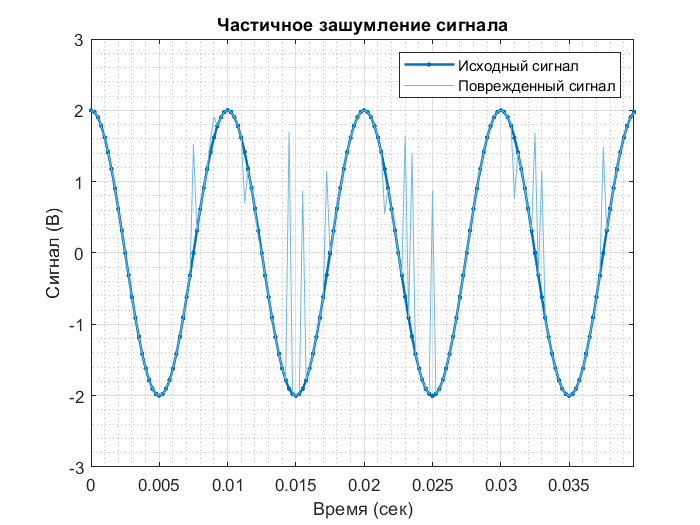

plot(Time,Signal,'.-','LineWidth',1.5); grid on; 
line(Time,SignalwithDefects,'Color',[109 185 226]/255); grid minor;
xlabel('Время (сек)'); ylabel('Сигнал (В)'); ylim([-1.5*A 1.5*A]);
title('Частичное зашумление сигнала'); xlim([Time(1) Time(end)]);
legend('Исходный сигнал','Поврежденный сигнал');

## 2. Выявление поврежденных ячеек

Используем кастомный алгоритм для выявления поврежденных ячеек:

R = zeros(1,N);
for i = 3:N-2
    if ((abs(SignalwithDefects(i)-SignalwithDefects(i-1))>maxVariation)&& ...
            (abs(SignalwithDefects(i)-SignalwithDefects(i+1))>maxVariation))|| ...
            ((abs(SignalwithDefects(i)-SignalwithDefects(i-2))>2*maxVariation)&& ...
            (abs(SignalwithDefects(i)-SignalwithDefects(i+2))>2*maxVariation))
        R(i) = i;
    end
end
R(R==0) = [];

Отобразим зафиксированные поврежденные отсчеты:

disp(['Количество обнаруженных неверных отсчетов: ',num2str(size(R,2)),'/',num2str(size(r,2)), ...
    ' (',num2str(round(size(R,2)/size(r,2)*100)),'%)']);

Количество обнаруженных неверных отсчетов: 16/16 (100%)


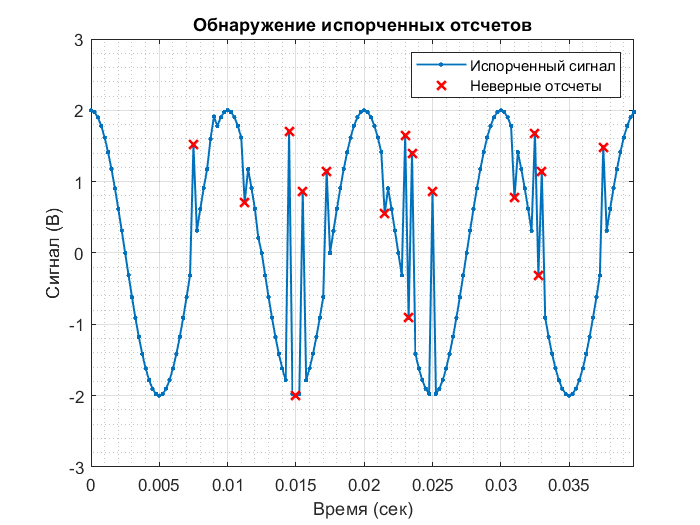

plot(Time,SignalwithDefects,'.-','LineWidth',1); grid on; grid minor; ylim([-1.5*A 1.5*A]);
line(Time(R),SignalwithDefects(R),'Color','Red','Marker','x','LineStyle','none', ...
    'MarkerSize',7.5,'LineWidth',1.5); xlim([Time(1) Time(end)]);
xlabel('Время (сек)'); ylabel('Сигнал (В)');
title('Обнаружение испорченных отсчетов'); 
legend('Испорченный сигнал','Неверные отсчеты');

## 3. Удаление неверных отсчетов и заполнение правильными значениями

Используем линейную интерполяцию для исправления неверных отсчетов:

SignalwithoutDefects          = SignalwithDefects;
SignalwithoutDefects(R)       = NaN;
[OutputSignal,missingIndices] = fillmissing(SignalwithoutDefects,'linear');

Отобразим выходной сигнал и исправленные данные:

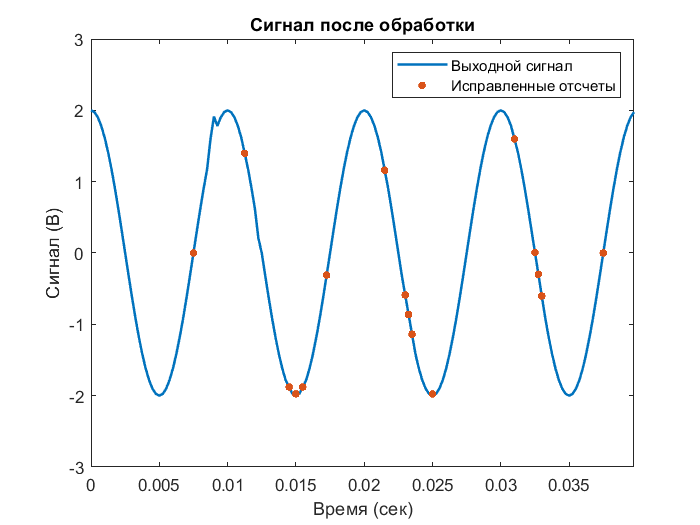

plot(Time,OutputSignal,'Color',[0 114 189]/255,'LineWidth',1.5); hold on;
line(Time(missingIndices),OutputSignal(missingIndices),'Marker','.','MarkerSize',12, ...
    'Color',[217 83 25]/255,'LineStyle','none'); xlim([Time(1) Time(end)]);
xlabel('Время (сек)'); ylabel('Сигнал (В)');
title('Сигнал после обработки'); ylim([-1.5*A 1.5*A]);
legend('Выходной сигнал','Исправленные отсчеты');